# Parameters Initialization

The script `Initialization.m` contains a template for initialization of MC-function variables. 

   MonteCarlo_Rect(...
       'with_air',false,...
       'is_fluor',false,'map_filename','map.mat',...
       'is_calculate_absorption_map',false,...
       'is_show_absorption_map',false,...
       'is_calculate_irradiance', true,...
       'is_show_irradiance',true,...
       'is_calculate_histograms',false,'d_hist',0.5,'d_r_hist',0.5, ...
       ...
       'result_filename','MC.mat',...
       ...
       'total_photons',1e7,...
       'ma',[0.13], 'ms',[11.9], 'g',[0.8],'n_in',[1.38],'n_out',[1 1],'n_air', 1,...
       ...
       'z',[0 6],'x',20,'y',20,...
       ...
       'dx',0.25,'dy',0.25,'dz',0.25,...
       ...
       'is_circle',false,'source_center', [10 10 0],'source_width',[1.7 2],...
       'with_PS',false,'wavelenght',405,...
       ...
       'is_calculate_directed_escape',false,'is_complex_detector',true,...
       'directed_escape_radius',[1.7,5],'directed_escape_refracted_angle',pi/180,...
       'is_calculate_TR',false,'T_radius', 8,'R_radius',8,...
       ...
       'is_het',false,'het_cylinder', false,'x0',5, 'a', 1,'y0', 5, 'b',1, 'z0',1,'c',1,'d',1,...
       'ma_het',0.2,'ms_het',1,'g_het',0.9,...
       ...
       'min_weight', 1e-5)

# Description

`pos `- photon position in cartesian coordinates

`dir` - direction cosines 

`weight` - photon weight 

`layer` - a layer of medium where a photon is travelling (from 0 to numel(z))

## Simulated configuration

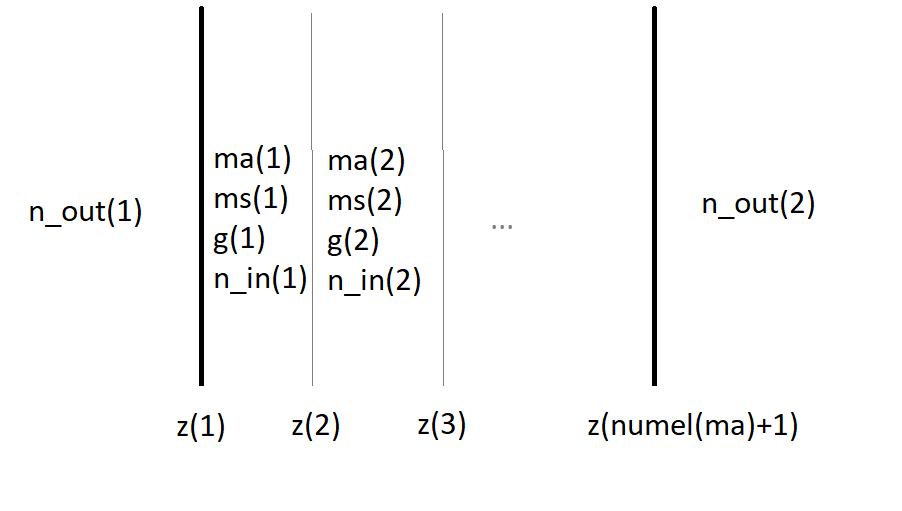

 'with_air',false,...

The parametes `with_air` is needed for accounting of [Fresnel reflection](https://www.rp-photonics.com/fresnel_reflections.html) at the launch step when photons is traveling from air to tissue layer. If `with_air = false`, photons start traveling from the first boundary, but air-tissue interaction isn't processed.

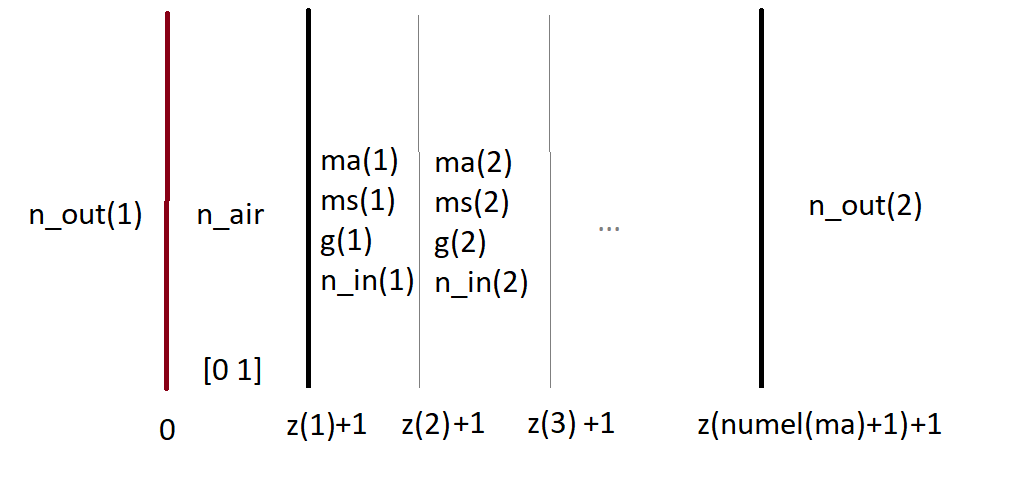

**NOTE: Air-tissue interaction for photons travelling from tissue to outside is processing  for all the time when a photon crosses the boundary **`z`**.  **

Variables `ma,ms,g, n_in` and `z` should contain just tissue parameters, air layer parameters are adding automatically.

If a photon moves from tissue layer to this air-layer, a photon would be considered as escaped. 

## Launch

- Launch_photons.m

[pos, dir, weight, max_deep, layer] = launch_photons(is_circle,source_center,source_width,source_direction, count, use_gpu)

Initialize photons parameters `pos, dir, weight, max_deep and layer `in accordance with source configuration. If `is_circle = true, `photon positions would be randomly initialized in the circle with the center in `source_center `and R = `source_width, `and z would be set equal 0. 

Parameters given in the following form:

source_center = [x_s y_s z_s];
source_width = R_s; 

If `is_circle = false,  `photon positions would be randomly initialized in the rectangle with the center in `source_center and `sides widths equal` source_width.`

Parameters given in the following form:

source_center = [x_s y_s z_s];
source_width = [a_s b_s]; 

Initial weights are set equal 1.

Initial max_deep is equal 0.

Initial layer is equal 1. (So, if` with_air = true`, photons start from z = 0 in the air layer ).

Initial direction is equal  `source_direction`, 

- Launch_photons_complex.m

[pos, dir, weight, max_deep, layer] = ...
    launch_photons_complex(source_map,x_grid,y_grid,z_grid,dx,dy,dz)

Initialize photons parameters `pos, dir, weight, max_deep and layer `in accordance with `source_map`. The matrix `source_map` is an absorption map served as fluorecence source. 

Initial position is equal to position of non-zero cell of `source_map`. 

Initial layer is equal 1.

Initial direction is isotropic.

Initial max_deep is equal `pos(:,3).`

The value in a non-zero cell of `source_map` is used as initial weights. For example, a non-zero cell contains 3.5. The script creates 3 photons with initial weights are equal 1 and 1 photons with initial weight equal 0.5. 

- Launch_photons_isotropic_point_source.m

[pos, dir, weight, max_deep, layer] = launch_photons_isotropic_point_source(count,source_center,z)

## Fluorescence

'is_fluor',true,'map_filename','map.mat',...

Photons are launched by launch_photon_complex.m (see Launch). Other steps are the same. 

## Absorption map

'is_calculate_absorption_map',true,...
       'is_show_absorption_map',true,...

Calculate a 3d matrix of absorption. Each element is a cube with dx, dy, dz sides. 

   function absorption = calculate_absorption_simple(photons_coords, weight, x_grid, y_grid, z_grid, absorption)

Sum up weights of photons in a grid element that matches photon position. 

`is_show_absorption_map `show log10 of a map in X and Z coordinates.

In case of  `with_air = true`, the air layer would be cut (the map would be without air layer). 

## Irradiance

'is_calculate_irradiance', true,...
       'is_show_irradiance',true,...

Calculate a 3d matrix of irradiance. Each element is a cube with dx, dy, dz sides. 

   function irradiance = calculate_irradiance_simple(photons_coords_prev, photons_coords, weight, x_grid, y_grid, z_grid, irradiance)

Sum up weights of photons in grid elements that were crossed by photon moving from previous position to actual position. 

`is_show_irradiance `show log10 of a irradiance map in X and Z coordinates.

In case of  `with_air = true`, the air layer would be cut (the map would be without air layer). 

## Modeling parameters

'ma',[0.13], 'ms',[11.9], 'g',[0.8],'n_in',[1.38],'n_out',[1 1],'n_air', 1,...
       ...
       'z',[0 6],'x',20,'y',20,...
       ...
       'dx',0.25,'dy',0.25,'dz',0.25,...

`ma, ms` and `g` are optical properties of tissue. The size of parameters is equal to number of layers. `z, x` and `y `- the size of tissue. 

`n_in `is  refractive index of tissue layers (The size  is equal to number of tissue layers).

`n_out `is refractive index of outside medium (typically, air). 

`n_air `is refractive index of additional air layer (see with_air descritption). 

`dx, dy `and `dz `are step sizes of grids. 

## C, T and R calculations

 'is_calculate_directed_escape',false,'is_complex_detector',true,...
       'directed_escape_radius',[1.7,5],'directed_escape_refracted_angle',pi/180,...
       'is_calculate_TR',false,'T_radius', 8,'R_radius',8,...

To calculate collimated transmittance set up `is_calculate_directed_escape = true. `if` is_complex_detector = true`, photons that leave the tissue from the side opposite the incident side would be counted as detected in case of their position  in the rectangle with` source_center` and `directed_escape_radius` sides (should be set in the form of` [x_d y_d]`) and angle of refraction less then `directed_escape_refracted_angle. `If `is_complex_detector = false, `photons would be detected in case of their position is in the circle with `source_center` and `directed_escape_radius `(should be set in the form of `[R]`).

To calculate diffuse transmittance and reflectance set `up is_calculate_TR = true`. Transmitted and reflected photons would be detected in case if photon position is in the detector circle (`with source_center` and `T_radius/R_radius`).

## Heterogeneity

'is_het',false,'het_cylinder', false,'x0',5, 'a', 1,'y0', 5, 'b',1, 'z0',1,'c',1,'d',1,...
       'ma_het',0.2,'ms_het',1,'g_het',0.9,.

If `is_het = true`, there is a heterogeneity with given optical properties (`ma_het, ms_het, g_het`) in tissue. 

`het_cylinder = true` means that the heterogeneity looks like a cylinder with center in `z0` and `y0`, and diameter `d`. 

`het_het_cylinder = false` means that the heterogeneity looks like a spheroid with center in `x0,y0` and `z0`, and semi-axes `a,b,c`. 

**Note: The difference in the refractive index is not considered.**

If at the steps of moving and absorption calculaition a photon is in a heterogeneity, for calculation of moving step and absorped weight the value of `ma_het, ms_het `and` g_het `are used. 

## Absorption

[weight, absorb, dweight] = absorb_photons(weight, ma, mt,out,layer,on,use_gpu,with_PS,ma_PS_conc,is_het,ma_het,mt_het,is_in_het);

Changes photons weights corresponding to the optical properties of surrounding tissue.

The absorbed fraction is calculated as `weight*ma/mt`. 

Checks heterogeneity (+ `ma_het`) and PS distribution(+`ma_PS`).

`absorb` is absorbed weight in the whole tissue. 

`dweight` is absorbed fraction for each photon.

## Scattering

dir = photon_scattering(dir, g, layer, is_need_recalculation, use_gpu,is_in_het,g_het);

Calculates scattering corresponding to the optical properties. 

## Refraction and Reflection

[pos, dir, layer, is_need_recalculation] = reflect_photons(pos, pos_previous, dir, layer, z, n, use_gpu);

If a photon crosses a boundary (between tissue layers or air-tissue boundary), a photon moves to the point of boundary intersection and refraction/reflection is checked. 

New photon directions are calculated and  layer is changed accordingly refraction/reflection checking. 

`is_need_recalculation` is photons that didn't cross the boundary. Scattering is calculated only for `is_need_recalculation `photons`. `